# Example 5.3: Pulsed Frequency Agile Radar

Nicholas O'Donoughue 1 July 2019

Consider a pulsed radar with a PRF of 2 kHz (PRI = 500 $$\mu$$s) and 20\% duty cycle ($$t_p = 125$ $\mu$$s), the same spectral characteristics (transmit and hopping bandwidth) as Example 5.2, and the ability to select a new frequency on each pulse.

What receiver bandwidth is necessary to detect each pulse with a desired frequency resolution of $$\delta_f=10$$ MHz?  What if $$\delta_f=100$$ kHz?

## Solution

First, we define the parameters of interest.

Thop_ms = [1, 0.1, 0.01]'; % ms
Bhop_MHz = 4000; % MHz
Bs_low_MHz = 0.1; % MHz
Bs_high_MHz = 10;% MHz
Bs_step_MHz = 0.1;% MHz
duty = 0.2; % Duty cycle (0-1)

Thop = Thop_ms / 1e3;
Bhop = Bhop_MHz * 1e6;
Bs = (Bs_low_MHz:Bs_step_MHz:Bs_high_MHz)*1e6;
tp = duty*Thop % pulse duration (seconds)

tp = 	1.0e+-3 *

    0.2000
    0.0200
    0.0020


The approach to this problem is the same as before, except that we must scan the entire band of interest during the pulse duration. Since each pulse will select a new frequency, the receiver must be able to scan the entire band of interest in $$t_p$$ seconds.

Tdwell = 1./Bs;
Nscan = tp./Tdwell;

From here, the computation for required receiver bandwidth is the same as in the previous example, and the results are plotted in the figure below for three different pulse durations, and a number of desired frequency resolutions. From this figure, we see that the required bandwidth for $$\delta_f=10$$ MHz (and $$t_p=125 \mu s$$) is $$B_r \geq 10$$ MHz, while for $$\delta_f=100$$ kHz, this increases to $$B_r \geq 200$$ MHz. If the pulse duration is further shortened, the dwell duration lengthens and the required receiver bandwidth increases correspondingly.

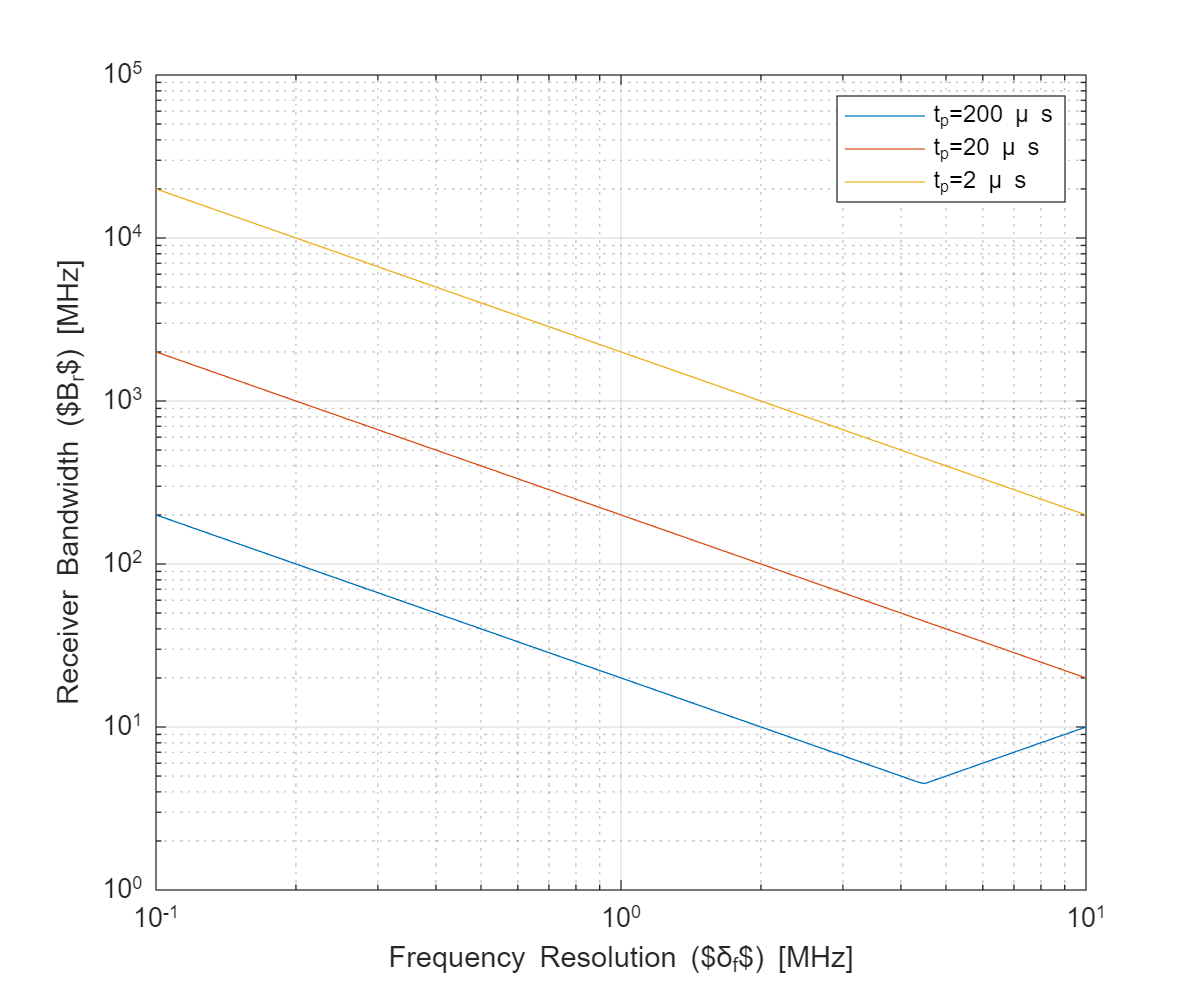

Br = max(Bs,Bhop./Nscan);

fig=figure;
loglog(Bs/1e6,Br/1e6);
xlabel('Frequency Resolution ($\delta_f$) [MHz]');
ylabel('Receiver Bandwidth ($B_r$) [MHz]');
legend(arrayfun(@(x) sprintf('t_p=%.0f \\mu s',x*1e6),tp,'UniformOutput',false));
grid on;